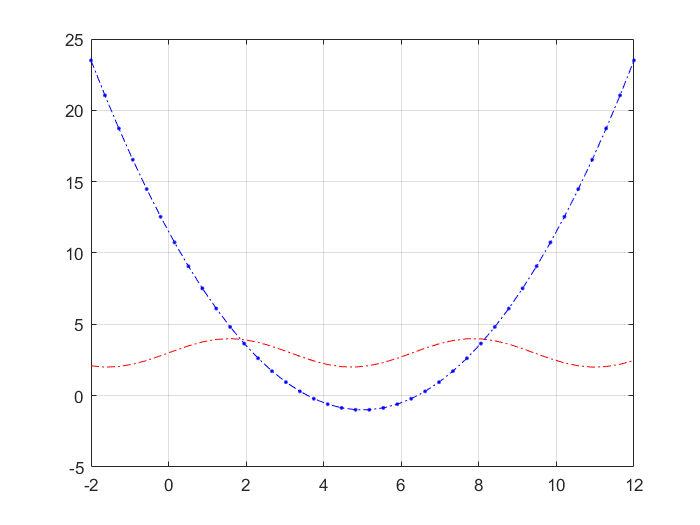

f = @(x) 3 + sin(x);
g = @(x) 0.5 * (x - 5).^2 - 1;

a = -2;
b = +12;
N = 40;

x = linspace(a, b, N);
plot(x, f(x), '-.r', x, g(x), '.-.b');
grid on;

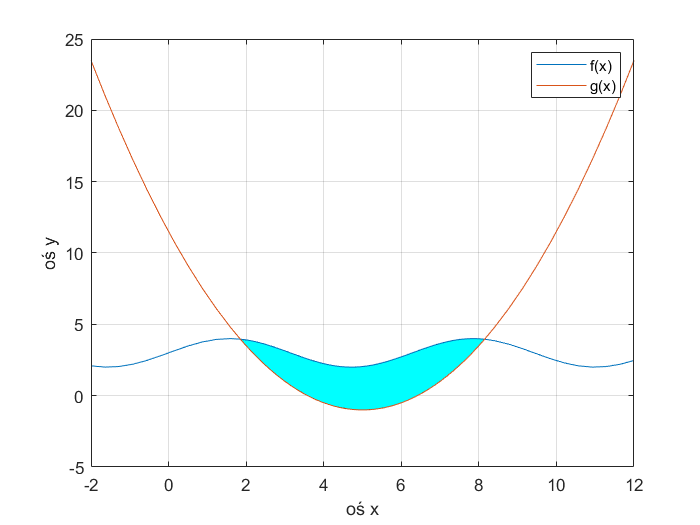

%można napisać nieanonimową w osobnej lini lub anonimową zawartą w fzero
h = @(x) f(x) - g(x);
xL = fzero(h, [-1000, 4.9999]);
xR = fzero(@(x) f(x) - g(x), [5.0001, 1000]);
xi = linspace(xL, xR, N);
up = f(xi);
down = g(xi);

xx = [xi, fliplr(xi)];
yy = [up, fliplr(down)];

fill(xx, yy, 'c');
hold all;

x = linspace(a, b, N);
x = [x, xx];
x = unique(x);
z = plot(x, f(x), x, g(x));
grid on;
xlabel 'oś x';
ylabel 'oś y';
legend(z, {'f(x)', 'g(x)'});